## Samuel Adkins

## Assignment 1 - COT 5930

### Important Note:

I chose to complete this assignment as a MATLAB app with options to select image, select filters, vizusalize before and after, and the option to save the filtered image.

The **MATLAB App** can be found at my file exchange or GitHub repo for this project: [**https://github.com/Aweesam/SimpleImageFiltering**](https://github.com/Aweesam/SimpleImageFiltering) or the [MATLAB File Exchange](https://www.mathworks.com/matlabcentral/fileexchange/158916-imagefilter).

**Installation: **The .mlappinstall file contains everything necessary to install and run the app. Download the app package [ImageFilter.mlappinstall](https://github.com/Aweesam/SimpleImageFiltering/blob/v1.0.3/ImageFilter.mlappinstall) and open it with MATLAB to run the app.

**Table of Content:**

**1) ****Select input image**

**2) ****Select image processing technique**

**3) ****See output**

**4) ****Save output as .png**

### Chose one of MATLAB's default images

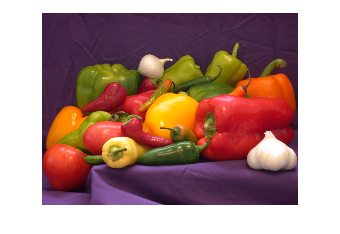

OriginalImg = imread("peppers.png");
imshow(OriginalImg)

### Select Image Processing Technique

filterType = "Background Isolation"

filterType = "Background Isolation"


% Check which filter is selected and apply it
switch filterType
    case 'No Filter'
        filteredImage = OriginalImg;
        
    case 'Box'
        % Apply box filter of Size 1
        filterSize = 1;
        filteredImage = imboxfilt(im2gray(OriginalImg), filterSize);
        
    case 'Gaussian'
        % Example of applying Gaussian blur
        filterSigma = 2;
        filteredImage = imgaussfilt(im2gray(OriginalImg),filterSigma);

    case 'Median'
        % Apply median filter for each pixel with med. val in
        % m-n neighborhood
        filteredImage = medfilt2(im2gray(OriginalImg), [3 3]);
     
    case 'Edge Detection (Sobel)'
        % Apply Sobel filter for edge detection
        filteredImage = edge(im2gray(OriginalImg), 'sobel');

    case 'Edge Detection (Canny)'
        % Apply Edge Detection using Canny method
        filteredImage = edge(im2gray(OriginalImg), 'Canny');

    case 'Edge Detection (Prewitt)'
        % Apply Edge Detection using Canny method
        filteredImage = edge(im2gray(OriginalImg), 'Prewitt');

    case 'Noise Removal'
        % Remove noise - filter size 5-by-5
        filteredImage = wiener2(im2gray(OriginalImg), [5 5]);

    case 'Background Isolation'
        % Convert to grayscale and threshold the image to create a mask
        grayImage = im2gray(OriginalImg);
        % Isolate the backgCround
        background = imopen(grayImage, strel('disk', 15));
        % Subtract the background
        filteredImage = imsubtract(grayImage, background);
    
    otherwise
        % If no filter is selected or recognized, display the original image
        filteredImage = app.OriginalImg;
end

### Filtered Image Output

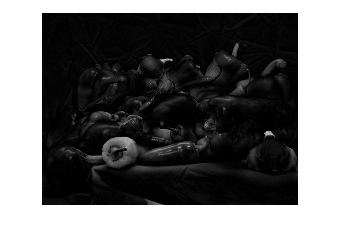

% Display the filtered image
imshow(filteredImage)

### Save Output as .PNG (optional)

 
imgExport = imshow(filteredImage);
saveas(imgExport, 'filteredImage.png');